# Euler Bernoulli beam with cubic spring and damper

% Generate model
clear all;
nElements = 25;
kappa = 6; % cubic spring
gamma = -0.02; % cubic damping
[M,C,K,fnl,f_0] = build_model(kappa, gamma, nElements);
n = length(M);
% Dynamical system setup 

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',3,'Nmax',10,'notation','multiindex')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} 
+ \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


epsilon = 0.01;

Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);
% Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 8.839900e-04
modal damping ratio for 2 mode is 5.485350e-03
modal damping ratio for 3 mode is 1.535575e-02

 The first 6 nonzero eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.0700i
  -0.0001 - 0.0700i
  -0.0024 + 0.4387i
  -0.0024 - 0.4387i
  -0.0189 + 1.2283i
  -0.0189 - 1.2283i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304


% Forced response curves using SSMs
% Obtaining *forced response curve* in reduced coordinate

order = 5; % SSM approximation order
outdof = n-1; %[n-1 n 2*n-1 2*n]; % degree of freedom at which output is displayed
freqRange = [6.96 7.04];
epsRange = [0.01 1]*epsilon;
optdof = outdof;
mFreq  = 1;
set(S.contOptions, 'h0',1e-3,'h_min',1e-3,'h_max',0.005, 'PtMX', 250);  % continuation setting
set(S.FRCOptions, 'initialSolver', 'fsolve');   % solver for initial solution
set(S.FRCOptions, 'coordinates','cartesian');
set(S.FRSOptions, 'calFRS', true);
set(S.Options, 'contribNonAuto', false, 'COMPtype', 'first');

**We calcuate the** **frequency response surface**.

(1) two-dimensional continuation based computation

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

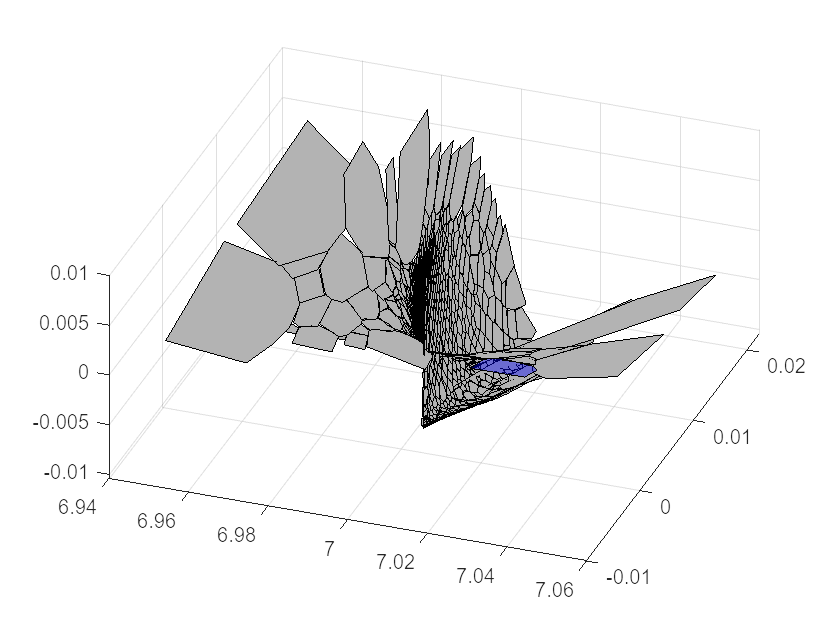

set(S.contOptions,'atlasdim',2, 'R', 0.01,'R_max',10,'R_min',1e-4,'almax',9.5,'PtMX',2000);
parRange = {freqRange,epsRange};
p0 = [6.97 0.5*epsilon]';
z0 = [1e-3 0]';
set(S.FRSOptions, 'method', 'continuation');
startfrs = tic;
S.extract_FRS('frs_cont',masterModes,order,mFreq,parRange,outdof,optdof,[],[],{p0,z0});

timings.FRS = toc(startfrs);

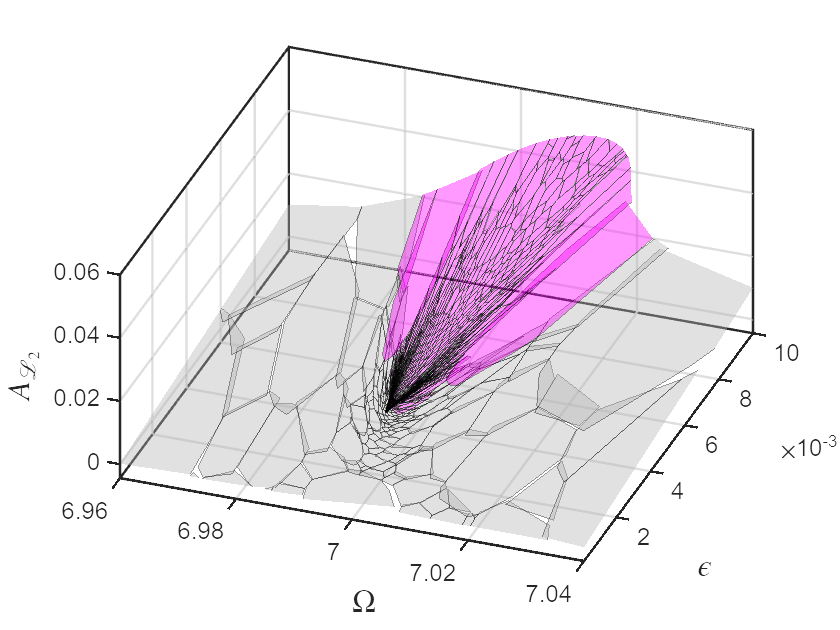

runid = 'frs_cont.FRSep';
figure;
plot_atlas_2d(runid, 1, 2, 5);
xlim(freqRange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$A_{\mathcal{L}_2}$','FontSize',16,'Interpreter',"latex");

(2) analytic prediction

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

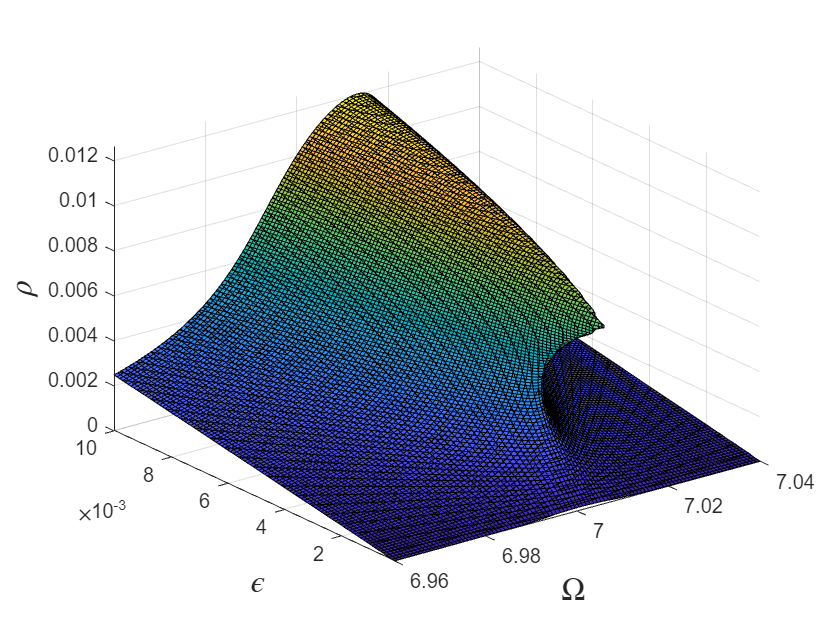

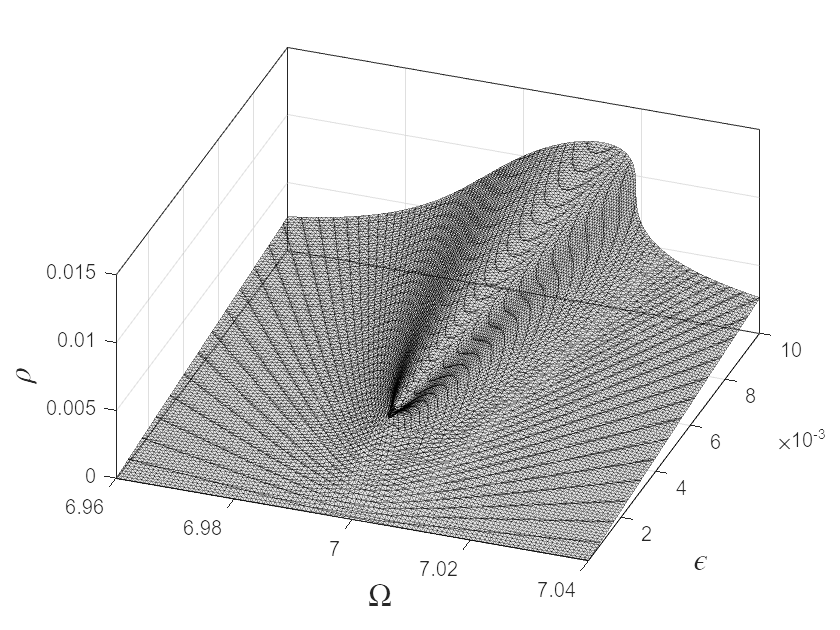

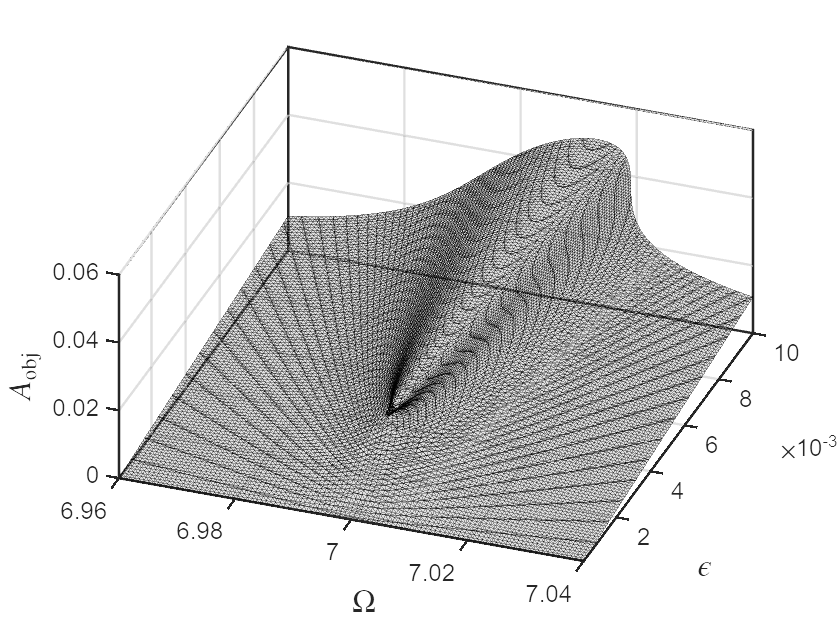

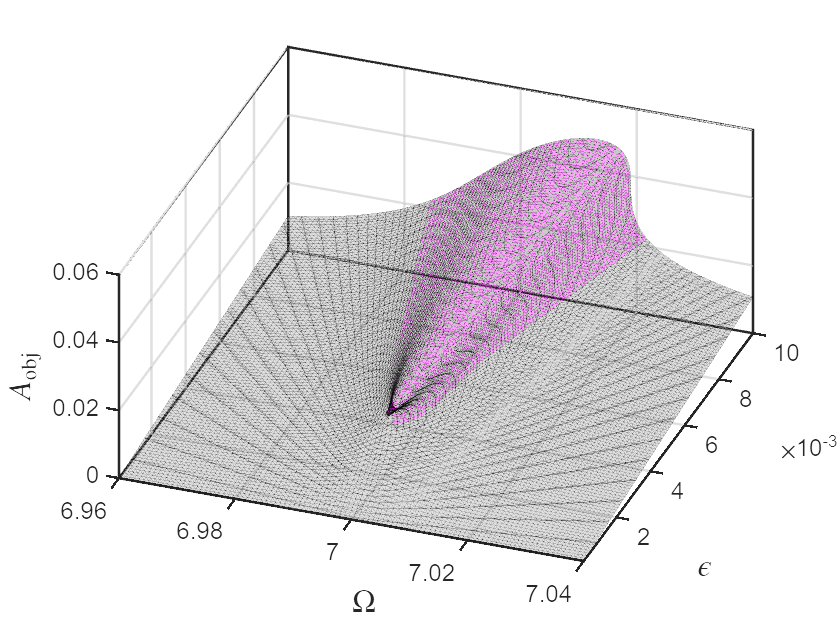

the number of faces is 42538


set(S.FRSOptions, 'method', 'level set');
tic
set(S.FRSOptions, 'rhoMax', 0.02, 'meshDens', 100);
S.extract_FRS('frs_ana',masterModes,order,1,parRange,outdof,optdof,[],[]);

toc

Elapsed time is 5.312247 seconds.
